# Correspondence Analysis (Task 2)

## Loading data

X = readtable("soft-drinks.xlsx", "Range", "A1:B1037")

X = 1036×2 table
      Word        Brand  
    _________    ________

    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}
    {'Teens'}    {'Coke'}


## Contingency Table

Cross-tabulation of variable **Word** on the rows

[cTable, chi2, pValue] = crosstab(X)

cTable = 10×6 table
                   Coke    V     RedBull    Fanta    Pepsi    DietCoke
                   ____    __    _______    _____    _____    ________

    Teens           69     46      41        13       22         18   
    PicksYouUp      29     52      45         3        5          3   
    Energy          19     55      47         2        3          1   
    EnjoyLife       50     22      19         8       10          7   
    WhenTired       25     38      33         2        4          3   
    Kids            30      2       1        45        8          2   
    Fun             35      6       5        32        5          2   
    Refre

chi2 = 396.6280

pValue = 8.6872e-58

### **p-value**

% the p-value is extremely negative, 
% however does not explicitly show anything.

## Contribution of each Brand

Chi2 index
  396.6280

pvalue Chi2 index
   8.6872e-58

Phi index
    0.6187

Cramer's V 
    0.2767

Test of H_0: independence between rows and columns
                   Coeff         se        zscore       pval   
                  ________    _________    ______    __________

    CramerV        0.27671      0.02242    12.342             0
    GKlambdayx     0.12358     0.022762    5.4291    5.6634e-08
    tauyx         0.083252    0.0088288    9.4296             0
    Hyx            0.11278     0.010518    10.722             0

-----------------------------------------
Indexes and 95% confidence limits
                   Value      StandardError    ConflimL    ConflimU
                  ________  

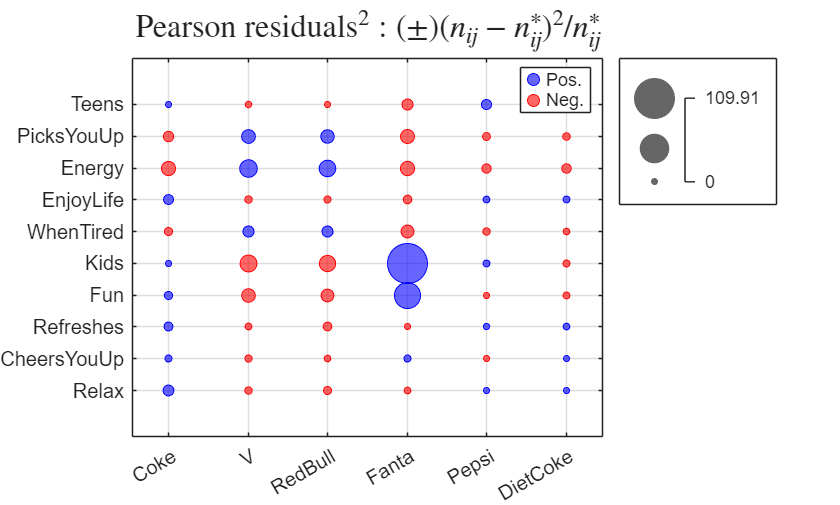

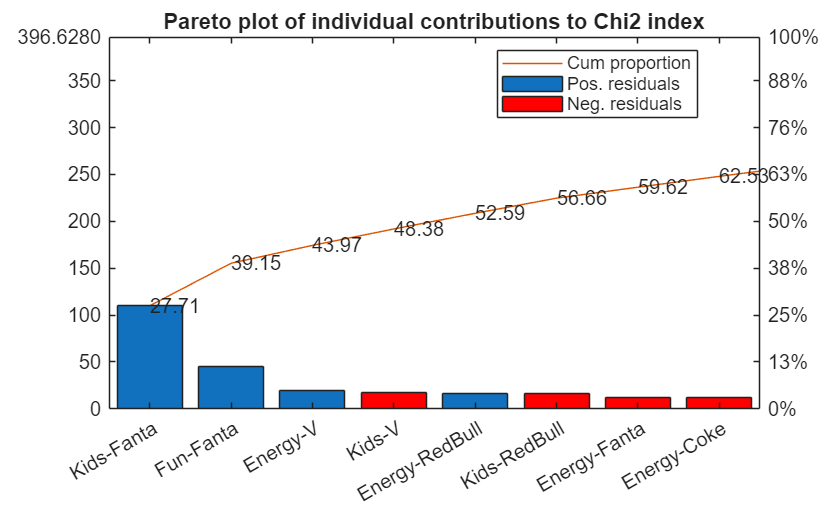

corrT = struct with fields:
                     N: [10×6 double]
                Ntable: [10×6 table]
                  Chi2: 396.6280
              Chi2pval: 8.6872e-58
                   Phi: 0.6187
               CramerV: [0.2767 0.0224 12.3420 0]
            GKlambdayx: [0.1236 0.0228 5.4291 5.6634e-08]
                 tauyx: [0.0833 0.0088 9.4296 0]
                   Hyx: [0.1128 0.0105 10.7223 0]
               ConfLim: [4×4 double]
          ConfLimtable: [4×4 table]
               TestInd: [4×4 double]
          TestIndtable: [4×4 table]
          Contrib2Chi2: [10×6 double]
     Contrib2Chi2table: [10×6 table]
           Contrib2Hyx: [10×6 double]
      Contrib2Hyxtable: [10×6 table]
         Contrib2tauyx: [10×6 double]
    Contrib2tauyxtable: [10×6 table]


% plots=True: generates a pareto plot and a plot to show the contribution
% of each cell of the contingecy table to the chi-square statistics
corrT = corrNominal(cTable, "plots", true)

**Comment on plot:**

The first plot illustrates that Kids have a strong interest towards **Fanta**, and negative interest/relationship towards drinks, such as **Redbull** and **V**. Moreover, most people considered V and Redbull as **Energy** drinks, however Fanta is considered a drink for **Fun**.

### Cramer's index

% strength of association
n = sum(cTable, "all").sum;
% Cramer's index
CramerV = sqrt(chi2 / (n * min(size(cTable) - 1)))

CramerV = 0.2767

**Comment:**

The value of Cramer's index is around 27%, which is significat and shows an association between the **Word** associated to the **Drink.**